# EXERCISE 2 LQR

m = 4500;
f = 0.028; % rolling resistance coefficient
g = 9.81;
Ca = 20000; % Cornering stiffness of each tire
lf = 1.01; % length from front tire to the center of mass
lr = 3.32; % length from rear tire to the center of mass
Iz = 29526.2; % Yaw intertia
delT = 0.032;
velocity = 30;

Symbolics

syms F_input x y x_dot y_dot psi_dot X Y s

Setup A B C D 

A = [0                  1                   0                   0
     0             -4*Ca/(m*x_dot)        4*Ca/m        -2*Ca*(lf-lr)/(m*x_dot)
     0                  0                   0                   1
     0      -2*Ca*(lf-lr)/(Iz*x_dot)  2*Ca*(lf-lr)/Iz   -2*Ca*(lf^2+lr^2)/(Iz*x_dot)];
     
B = [0             
    2*Ca/m        
      0             
      2*Ca*lf/Iz]

B =          0
    8.8889
         0
    1.3683



C = eye(4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



D = zeros(4,1)

D =      0
     0
     0
     0


Substitute x_dot in A matrix

A = [0      1       0       0
     0      -16/27  160/9   154/225
     0      0       0       1
     0      846623953387520/8116100056009933 -42000/13421 -66204343887462392/121741500850148995];


Get system dodel

plant = ss(A,B,C,D);
sysd = c2d(plant,delT)

sysd =
 
  A = 
              x1         x2         x3         x4
   x1          1     0.0317   0.009031  0.0004423
   x2          0     0.9813     0.5622    0.03049
   x3          0  5.275e-05     0.9984    0.03171
   x4          0   0.003276   -0.09829     0.9812
 
  B = 
              u1
   x1   0.004529
   x2     0.2824
   x3  0.0007013
   x4    0.04385
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 0.032 seconds
Discrete-time state-space model.



LQR controller design

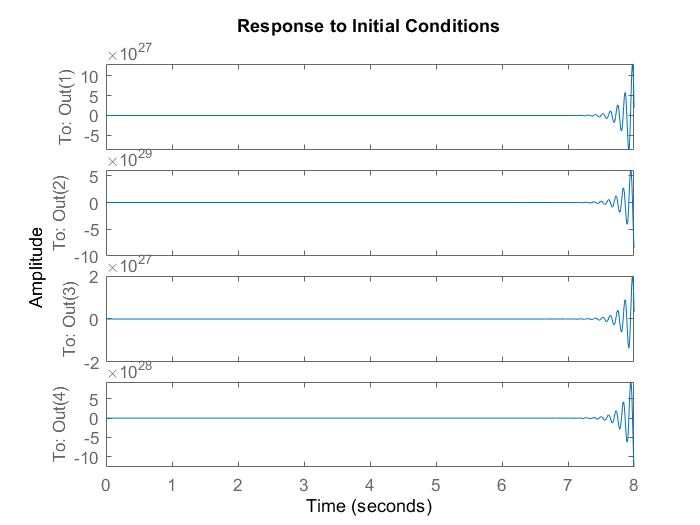

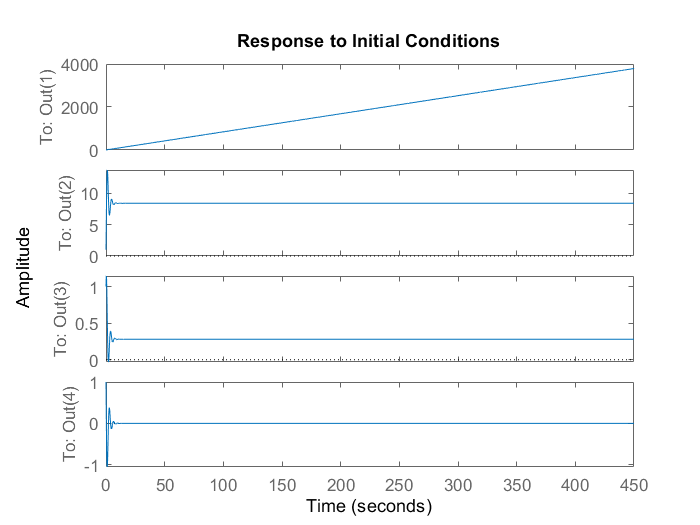

% First test
% Vehicle can almost follow the straight line but go off at first turn
Q = diag([1 1 1 1]);
R = 10;
K = -lqr(sysd.A,sysd.B,Q,R);

% Second test
% Increase R to increase stability
% Vehicle can follow the track, but avgDev is off
Q = diag([1 1 1 1]);
R = 100;
K = -lqr(sysd.A,sysd.B,Q,R);

% Tests
% Different tests are made based on changing different values and check
% results. Based on tests, increaing R will result in smaller deviation
% and best value is found at 1500 (ratio between R and Q is important!)
% Final test
% Vehicle moves along the track and can turn also along the track with
% little deviation
Q = diag([0.00000001 70 300 0.1]);
R = 1500;
K = -lqr(sysd.A,sysd.B,Q,R);